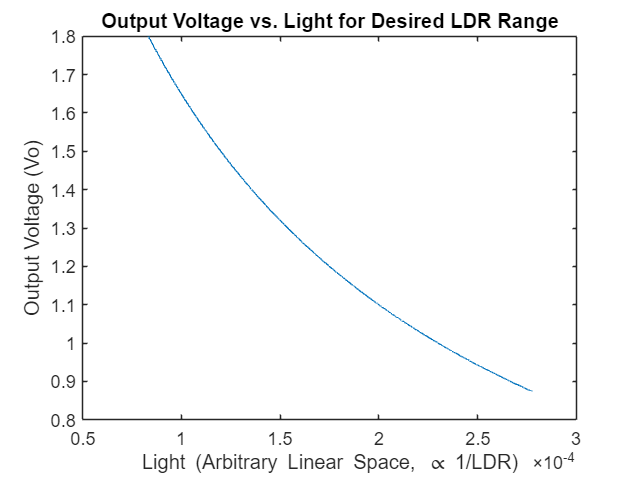

% Define the desired LDR range
R_max = 12000; % Maximum LDR value
R_min = 3600;  % Minimum LDR value

NPoints = 12000; 

% 1. Create a linearly spaced variable 'x' from 1/R_max to 1/R_min
% This effectively creates a linear space for the *reciprocal* of the LDR
x_min = 1/R_max;
x_max = 1/R_min;
x = linspace(x_min, x_max, NPoints); 

% 2. Calculate LDR as the reciprocal of x
ldr = 1./x; 
% ldr will now range from 1/x_min = R_max (12000) down to 1/x_max = R_min (3600)

% (Optional: Calculate a 'light' variable that is linearly spaced with 'x')
light = x; % 'light' is now the linear space, conceptually proportional to 1/ldr.
% You can scale 'light' if you want its axis to represent a certain illuminance range
% For example: light = 1000 * x; 
% For this plot, using 'x' as the linear base is clearest.

% 3. Keep the rest of the code the same (assuming 'light' is the x-axis)
res = 10000 * ones(1, NPoints); 
vi = 3.3; 
vo = vi* (ldr./(ldr + res)); 

figure 
plot(light, vo) 
xlabel('Light (Arbitrary Linear Space, \propto 1/LDR)')
ylabel('Output Voltage (Vo)')
title('Output Voltage vs. Light for Desired LDR Range')